# Lab 6 - Linear Algebra Functions

## Matrix Vector Operation

A = [4 -1 2];
B = [2 -2 -1];
disp(A.*B); %elementwise multiplication

     8     2    -2




c = A.*(B.');% B.' is the transpose of B
disp(c);

     8    -2     4
    -8     2    -4
    -4     1    -2



## Elimination

C = (A.').*A;
disp(C);

    16    -4     8
    -4     1    -2
     8    -2     4



r = rref(C); %get row reduced echelon form of C
disp(r);

    1.0000   -0.2500    0.5000
         0         0         0
         0         0         0




c_noise = C;
c_noise(1,2)=c_noise(1,2)-.0001;
c_noise(2,3)=c_noise(2,3)-.0001; %add noise to C matrix
disp(c_noise);

   16.0000   -4.0001    8.0000
   -4.0000    1.0000   -2.0001
    8.0000   -2.0000    4.0000



r2 = rref(c_noise);
disp(r2);

     1     0     0
     0     1     0
     0     0     1



If you use the "rref" function again, what is the rank of C_noise? Use one or two sentences to comment the difference between rank(C) and rank(C_noise), which rank should be used?

The rank(C) has a rank of 1 whereas rank(C_noise) has a rank of 3. The rank of C_noise should be used because the rank is equal to the amount of rows and columns the matrix has.  

U1 = my_elimination(C);

    16    -4     8
     0     0     0
     0     0     0



M=magic(3);
U2 = my_elimination(M);

    8.0000    1.0000    6.0000
         0    4.6250    4.7500
         0         0   -9.7297



U3 = my_elimination(eye(3));

     1     0     0
     0     1     0
     0     0     1



%refer to my_elimination.m file for how the function works

## Inverse

disp(inv(C));

   Inf   Inf   Inf
   Inf   Inf   Inf
   Inf   Inf   Inf



disp(inv(c_noise));

   1.0e+04 *

   -0.2500    0.5000    0.7500
   -1.0000         0    2.0000
         0   -1.0000   -0.5000



%inv functions gets the inverse of the matrix
[U,S,V] = svd(c_noise);
disp(U);

   -0.8729   -0.2731   -0.4044
    0.2182   -0.9597    0.1770
   -0.4364    0.0663    0.8973



disp(S);

   21.0000         0         0
         0    0.0001         0
         0         0    0.0000



disp(V);

   -0.8729   -0.3369    0.3530
    0.2182    0.3776    0.8999
   -0.4364    0.8625   -0.2560




[U,S,V] = svd(C);
disp(U);

   -0.8729   -0.4880   -0.0000
    0.2182   -0.3904    0.8944
   -0.4364    0.7807    0.4472



disp(S);

   21.0000         0         0
         0    0.0000         0
         0         0    0.0000



disp(V);

   -0.8729   -0.4880         0
    0.2182   -0.3904   -0.8944
   -0.4364    0.7807   -0.4472



## LU Decomposition

[L,U,P] = lu(C); %finds PC = LU
disp(L);

    1.0000         0         0
   -0.2500    1.0000         0
    0.5000         0    1.0000



disp(U); 

    16    -4     8
     0     0     0
     0     0     0



disp(P);

     1     0     0
     0     1     0
     0     0     1



## Null Space

N_hand = [0.25 -0.5; 1 0; 0 1]; %null space by hand
disp(N_hand);

    0.2500   -0.5000
    1.0000         0
         0    1.0000




N = null(C); %null space through matlab
disp(N);

   -0.4880         0
   -0.3904   -0.8944
    0.7807   -0.4472




disp(C*N);

   1.0e-14 *

    0.0888    0.1332
   -0.0222   -0.0333
    0.0444    0.0666



## Explore A^n

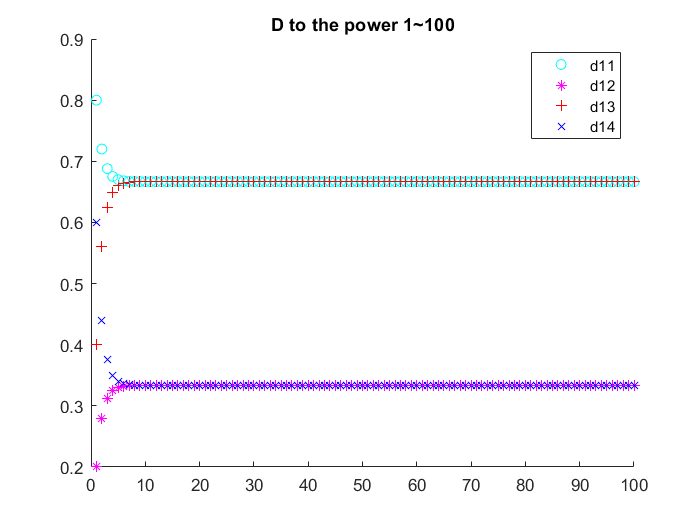

D = [0.8 0.2; 0.4 0.6];
E = [0.7 0.2; 0.4 0.6];
F = [0.9 0.2; 0.4 0.6];

Dn=zeros(2,2,100);
En=zeros(2,2,100);
Fn=zeros(2,2,100);

for n=1:100
    Dn(:,:,n)=D^n;
    En(:,:,n)=E^n;
    Fn(:,:,n)=F^n;
end

figure
hold on
title('D to the power 1~100')
for n=1:100
    plot (n,Dn(1,1,n), 'oc');
    plot (n,Dn(1,2,n), '*m');
    plot (n,Dn(2,1,n), '+r');
    plot (n,Dn(2,2,n), 'xb');
end
legend("d11", "d12", "d13", "d14");

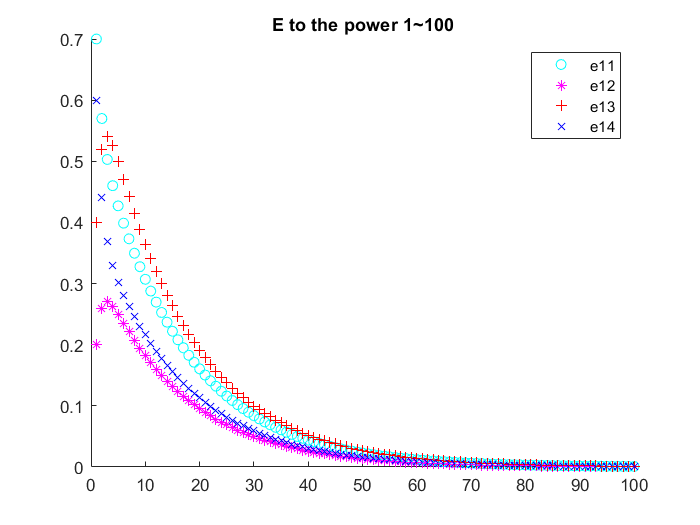


figure
hold on
title('E to the power 1~100')
for n=1:100
    plot (n,En(1,1,n), 'oc');
    plot (n,En(1,2,n), '*m');
    plot (n,En(2,1,n), '+r');
    plot (n,En(2,2,n), 'xb');
end
legend("e11", "e12", "e13", "e14");

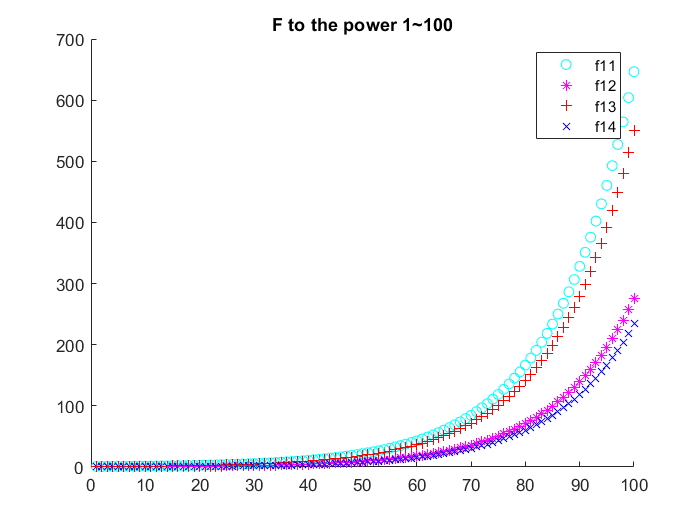


figure
hold on
title('F to the power 1~100')
for n=1:100
    plot (n,Fn(1,1,n), 'oc');
    plot (n,Fn(1,2,n), '*m');
    plot (n,Fn(2,1,n), '+r');
    plot (n,Fn(2,2,n), 'xb');
end
legend("f11", "f12", "f13", "f14");